Data

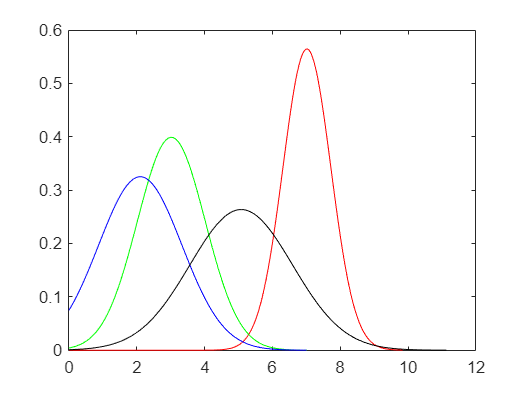

clear
load mnklasse1.dat
load mnklasse2.dat
load mnklasse3.dat
load mnklasse4.dat
load uklas.dat

meanMNklasse1=mean(mnklasse1);
sigma1=sqrt(var(mnklasse1));
xA=[0:0.01:4*sigma1(1)+meanMNklasse1(1)];
yA=normpdf(xA,meanMNklasse1(1),sigma1(1));
xB=[0:0.01:4*sigma1(2)+meanMNklasse1(2)];
yB=normpdf(xB,meanMNklasse1(2),sigma1(2));
xC=[0:0.01:4*sigma1(3)+meanMNklasse1(3)];
yC=normpdf(xC,meanMNklasse1(3),sigma1(3));
xD=[0:0.01:4*sigma1(4)+meanMNklasse1(4)];
yD=normpdf(xD,meanMNklasse1(4),sigma1(4));

plot(xA,yA,'red')
hold on
plot(xB,yB,'green')
plot(xC,yC,'blue')
plot(xD,yD,'black')
hold off

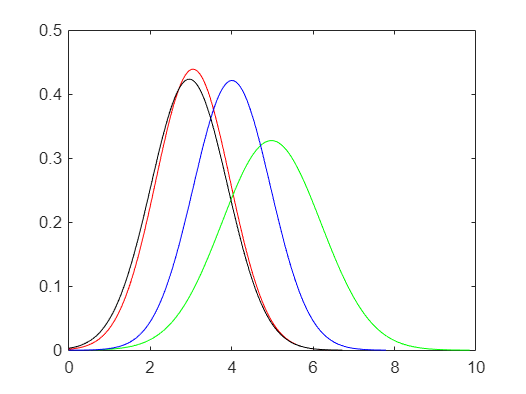



meanMNklasse2=mean(mnklasse2);
sigma2=sqrt(var(mnklasse2));
xA=[0:0.01:4*sigma2(1)+meanMNklasse2(1)];
yA=normpdf(xA,meanMNklasse2(1),sigma2(1));
xB=[0:0.01:4*sigma2(2)+meanMNklasse2(2)];
yB=normpdf(xB,meanMNklasse2(2),sigma2(2));
xC=[0:0.01:4*sigma2(3)+meanMNklasse2(3)];
yC=normpdf(xC,meanMNklasse2(3),sigma2(3));
xD=[0:0.01:4*sigma2(4)+meanMNklasse2(4)];
yD=normpdf(xD,meanMNklasse2(4),sigma2(4));
plot(xA,yA,'red')
hold on
plot(xB,yB,'green')
plot(xC,yC,'blue')
plot(xD,yD,'black')
hold off

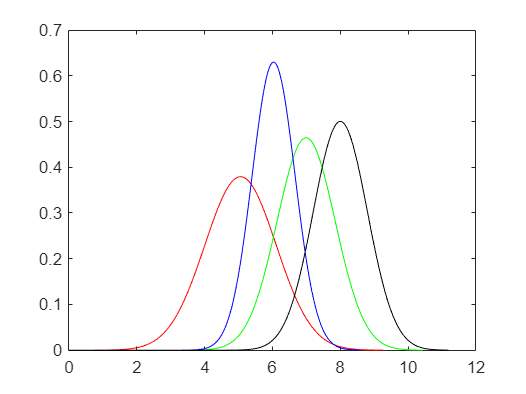



meanMNklasse3=mean(mnklasse3);
sigma3=sqrt(var(mnklasse3));
xA=[0:0.01:4*sigma3(1)+meanMNklasse3(1)];
yA=normpdf(xA,meanMNklasse3(1),sigma3(1));
xB=[0:0.01:4*sigma3(2)+meanMNklasse3(2)];
yB=normpdf(xB,meanMNklasse3(2),sigma3(2));
xC=[0:0.01:4*sigma3(3)+meanMNklasse3(3)];
yC=normpdf(xC,meanMNklasse3(3),sigma3(3));
xD=[0:0.01:4*sigma3(4)+meanMNklasse3(4)];
yD=normpdf(xD,meanMNklasse3(4),sigma3(4));
plot(xA,yA,'red')
hold on
plot(xB,yB,'green')
plot(xC,yC,'blue')
plot(xD,yD,'black')
hold off

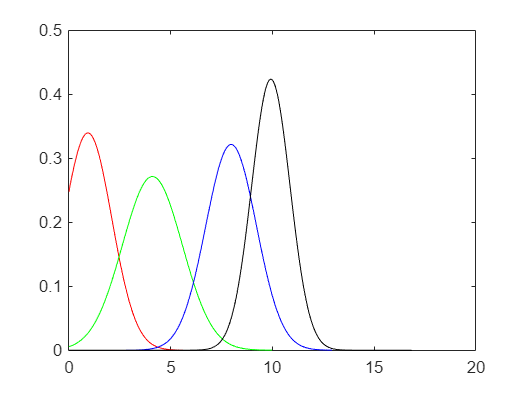


meanMNklasse4=mean(mnklasse4);
sigma4=sqrt(var(mnklasse4));
xA=[0:0.01:4*sigma4(1)+meanMNklasse4(1)];
yA=normpdf(xA,meanMNklasse4(1),sigma4(1));
xB=[0:0.01:4*sigma4(2)+meanMNklasse4(2)];
yB=normpdf(xB,meanMNklasse4(2),sigma4(2));
xC=[0:0.01:4*sigma4(3)+meanMNklasse4(3)];
yC=normpdf(xC,meanMNklasse4(3),sigma4(3));
xD=[0:0.01:4*sigma4(4)+meanMNklasse4(4)];
yD=normpdf(xD,meanMNklasse4(4),sigma2(4));
plot(xA,yA,'red')
hold on
plot(xB,yB,'green')
plot(xC,yC,'blue')
plot(xD,yD,'black')
hold off


cov1=cov(mnklasse1);
cov2=cov(mnklasse2);
cov3=cov(mnklasse3);
cov4=cov(mnklasse4);

K-nearest neighbor

data=[mnklasse1;
      mnklasse2;
      mnklasse3;
      mnklasse4];
%simple with only the closest
kplace=knnsearch(data,uklas)

kplace =    345
   207
   342
   307
   279
   127
    74
     4
   266
    28


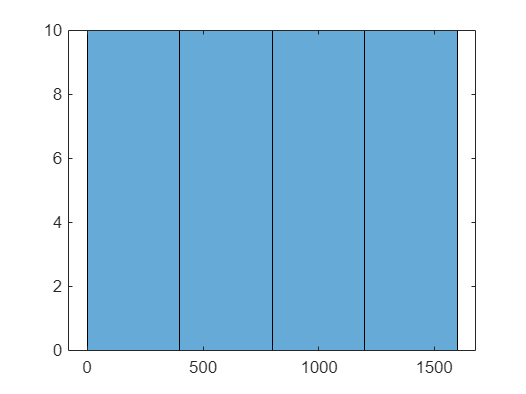

histogram(kplace,4)


%with several
kplace=knnsearch(data,uklas,'K',5)

kplace =    345    40   141   124   376
   207   306    95   280   185
   342   172   216    37   234
   307    97    57   312    67
   279   349   363   330   227
   127   291    34   151   197
    74   126    94   334    90
     4   138   293   197   160
   266   143   162   254   209
    28    56   123   148   358


Bayes distrubution

Pkl1=@(x) (normpdf(x(1),meanMNklasse1(1),sigma1(1))+normpdf(x(2),meanMNklasse1(2),sigma1(2))+normpdf(x(3),meanMNklasse1(3),sigma1(3))+normpdf(x(4),meanMNklasse1(4),sigma1(4)))/4;
Pkl2=@(x) (normpdf(x(1),meanMNklasse2(1),sigma2(1))+normpdf(x(2),meanMNklasse2(2),sigma2(2))+normpdf(x(3),meanMNklasse2(3),sigma2(3))+normpdf(x(4),meanMNklasse2(4),sigma2(4)))/4;
Pkl3=@(x) (normpdf(x(1),meanMNklasse3(1),sigma3(1))+normpdf(x(2),meanMNklasse3(2),sigma3(2))+normpdf(x(3),meanMNklasse3(3),sigma3(3))+normpdf(x(4),meanMNklasse3(4),sigma3(4)))/4;
Pkl4=@(x) (normpdf(x(1),meanMNklasse4(1),sigma4(1))+normpdf(x(2),meanMNklasse4(2),sigma4(2))+normpdf(x(3),meanMNklasse4(3),sigma4(3))+normpdf(x(4),meanMNklasse4(4),sigma4(4)))/4;

Pkl=@(x) [Pkl1(x),Pkl2(x),Pkl3(x),Pkl4(x)];

for i=1:1:length(uklas)
    [maxval(i),idx(i)]=max(Pkl(uklas(i,:))); 
end
min(maxval)

ans = 0.1600

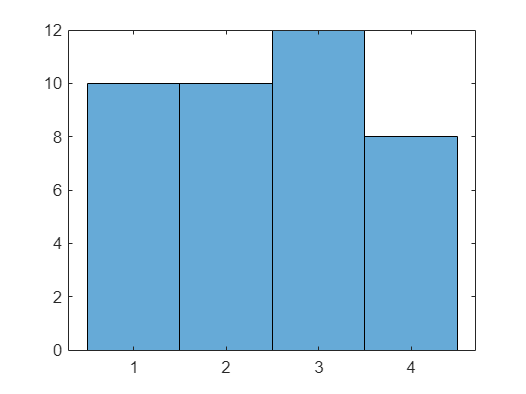

histogram(idx)